# Lab 2 Problema 2: Estudio de la dinámica de una masa  suspendida de una cuerda elástica cuya rigidez de extensión es  y longitud sin deformar.

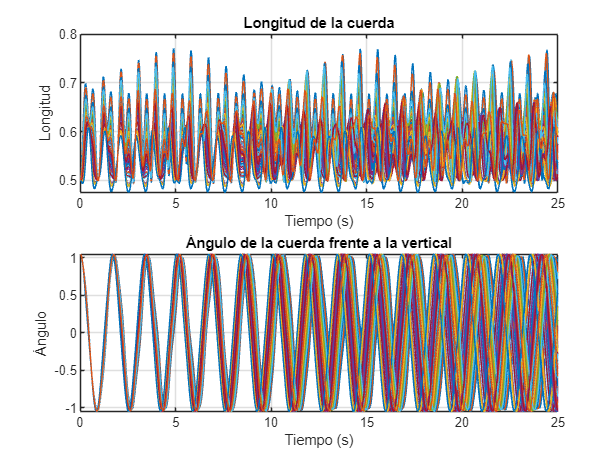

clear all; close all

% Condiciones iniciales nominales
L_nominal = 0.5;
L_variation = 0.02;

% Número de muestras
num_samples = 100;

% Realizar el muestreo de condiciones iniciales
L = L_nominal + L_variation * randn(num_samples, 1);

% Configuración de la simulación
t = 0:0.001:25;  % Tiempo de simulación

% Inicializar matrices para almacenar las respuestas
r_s = zeros(num_samples, length(t));
theta_s = zeros(num_samples, length(t));

% Simular cada sistema
for i = 1:num_samples
    % Asignar condiciones iniciales  
    set_param('lab2_prob2/L', 'Value', num2str(L(i)));

    % Ejecutar la simulación
    simOut = sim('lab2_prob2', 'StopTime', num2str(t(end)));
    
    t = simOut.tout;
    r_s(i,:) = simOut.r;
    theta_s(i,:) = simOut.theta;
end

% Mostrar resultados
figure;
subplot(2,1,1);
plot(t, r_s)
title('Longitud de la cuerda');
xlabel('Tiempo (s)');
ylabel('Longitud');
grid on;
hold on

subplot(2,1,2);
plot(t, theta_s);
title('Ángulo de la cuerda frente a la vertical');
xlabel('Tiempo (s)');
ylabel('Ángulo');
grid on;

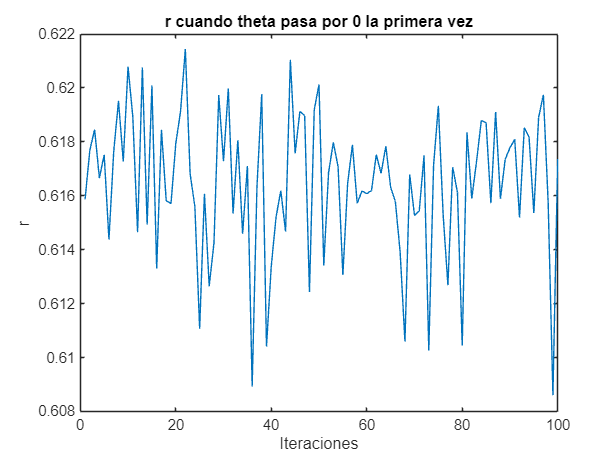


%% Obtener los valores de r donde theta es 0 por primera vez.
r_dis = zeros(1, size(theta_s, 1));
for k = 1:size(theta_s, 1)
    [r_min, index] = min(abs(theta_s(k, 1:600)));
    r_dis(k) = r_s(k, index);
end

figure
plot(r_dis)
title('r cuando theta pasa por 0 la primera vez');
xlabel('Iteraciones');
ylabel('r');

pd = fitdist(r_dis', 'Normal'); % Ajusta una distribución normal
mu = pd.mu;    % Media estimada
sigma = pd.sigma;  % Desviación estándar estimada

% Mostrar los parámetros de la distribución ajustada
fprintf('Media ajustada: %.4f m\n', mu);

Media ajustada: 0.6165 m


fprintf('Desviación estándar ajustada: %.4f m\n', sigma);

Desviación estándar ajustada: 0.0027 m


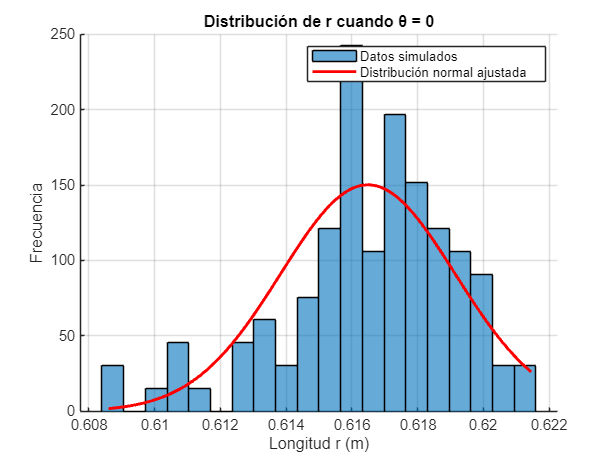


% Superponer la distribución normal sobre el histograma
x = linspace(min(r_dis), max(r_dis), 100);
pdf_normal = normpdf(x, mu, sigma);

figure, hold on;
histogram(r_dis, 20, 'Normalization', 'pdf'); % Normalizar histograma
plot(x, pdf_normal, 'r', 'LineWidth', 2); % Distribución normal ajustada
legend('Datos simulados', 'Distribución normal ajustada');
xlabel('Longitud r (m)');
ylabel('Frecuencia');
title('Distribución de r cuando θ = 0');
grid on;
hold off;

[h, p] = kstest((r_dis - mu) / sigma);

if h == 0
    disp('No se rechaza la hipótesis de normalidad (p > 0.05)');
else
    disp('Se rechaza la hipótesis de normalidad (p < 0.05)');
end

No se rechaza la hipótesis de normalidad (p > 0.05)
